Simulation of Robot

2019.3.26-27

Missions:

1. u=dx/dt;

2. u=dv/dt; v=dx/dt;

3. x,y

4. target xd,yd

5. feedback loop

6. moving target

7.rotation

8.final

1. u=dx/dt;

clear;
clc;

%create L1 and initial input x0
L1=[0 0 0;-0.5 1 -0.5;0 -1 1];
L1=-L1;

x0=[1 2 3]';

display('L1 and initial input x0:')

L1 and initial input x0:


L1,x0

L1 =          0         0         0
    0.5000   -1.0000    0.5000
         0    1.0000   -1.0000


x0 =      1
     2
     3



%simulink and display
sim('cluster_robot_control_1_dx',20);

display('Result display:')

Result display:


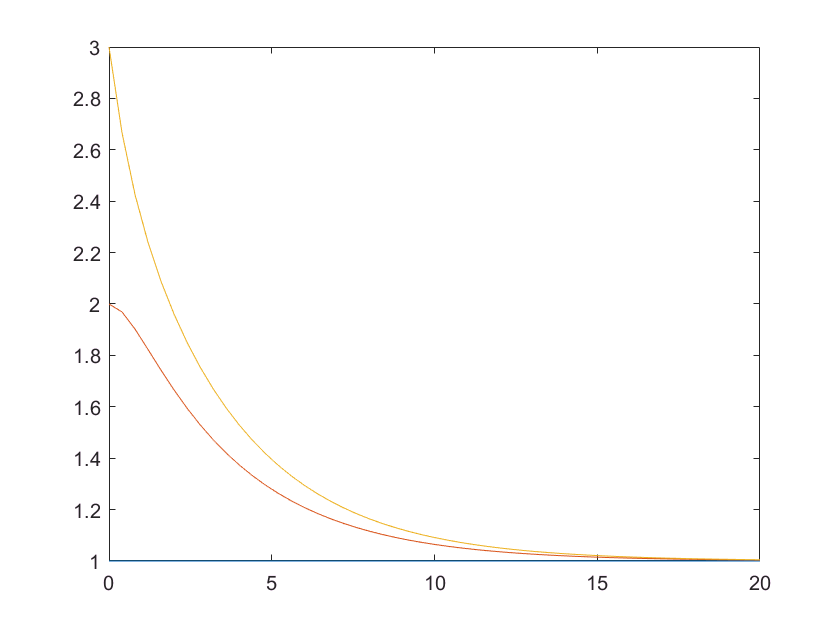

t=x(:,1);
x1=x(:,2);
x2=x(:,3);
x3=x(:,4);
plot(t,x1,t,x2,t,x3)

2. u=dv/dt; v=dx/dt;

clear;
clc;

%create L1 and initial input x0
L1=[0 0 0;-0.5 1 -0.5;0 -1 1];
L1=-L1;

E=eye(3);

x0=[1 2 3]';
v0=[1 2 3]';

display('L1 and initial input x0:')

L1 and initial input x0:


L1,x0,v0

L1 =          0         0         0
    0.5000   -1.0000    0.5000
         0    1.0000   -1.0000


x0 =      1
     2
     3


v0 =      1
     2
     3



%simulink and display
sim('cluster_robot_control_2_dxdv',20);

display('Result display:')

Result display:


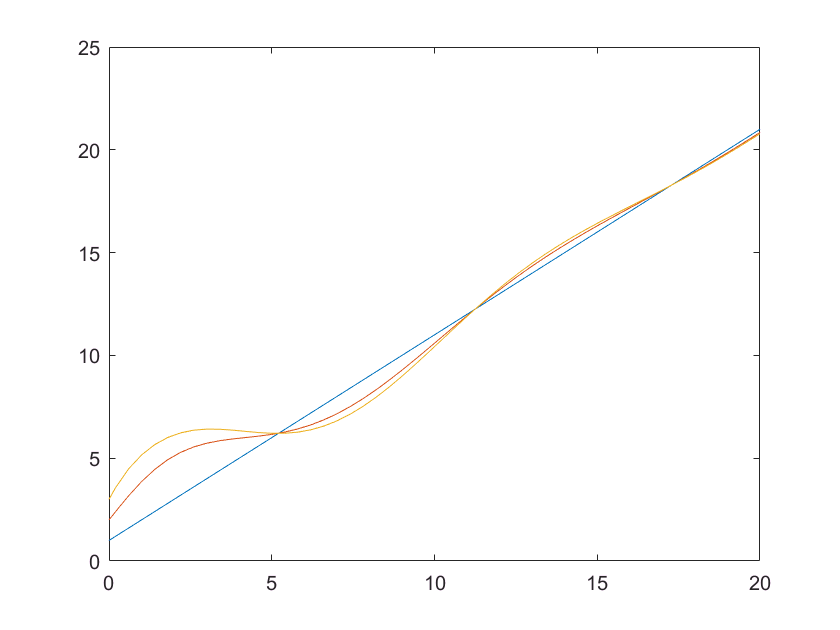

t=x(:,1);
x1=x(:,2);
x2=x(:,3);
x3=x(:,4);
plot(t,x1,t,x2,t,x3)

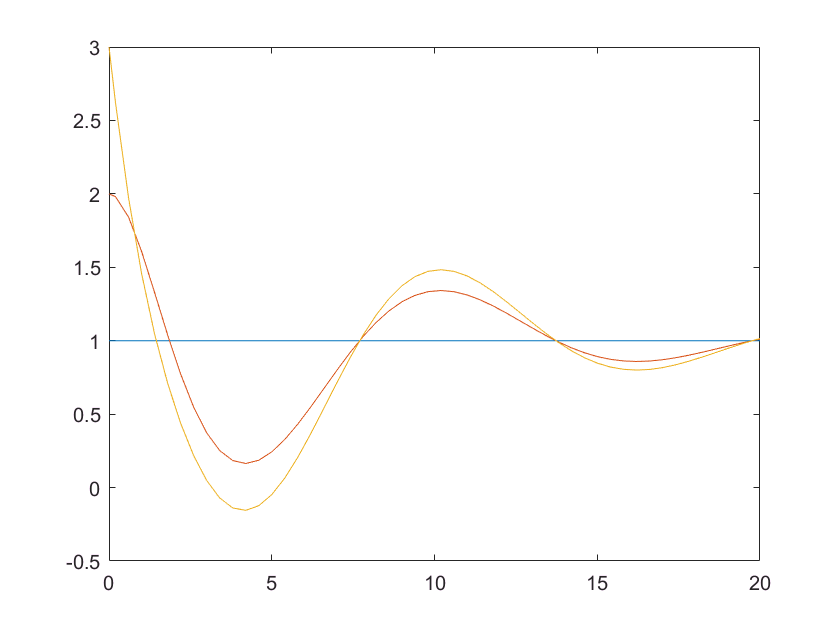


figure
t=v(:,1);
v1=v(:,2);
v2=v(:,3);
v3=v(:,4);
plot(t,v1,t,v2,t,v3)

3. x,y

clear;
clc;

%create L1 and initial input x0
L1=[1 0 0 -1;-1 1 0 0;0 -1 1 0;0 0 -1 1];
I2=eye(2);
LK1=kron(L1,I2);
LK1=-LK1;

E=eye(8);

x0=[1 3 2 1 3 2 4 5]';
v0=[1 1 2 1 1 1 1 1]';

display('Initial parameter:')

Initial parameter:


L1,x0,v0

L1 =      1     0     0    -1
    -1     1     0     0
     0    -1     1     0
     0     0    -1     1


x0 =      1
     3
     2
     1
     3
     2
     4
     5


v0 =      1
     1
     2
     1
     1
     1
     1
     1



%simulink and display
sim('cluster_robot_control_3_xy',20);

display('Result display:')

Result display:


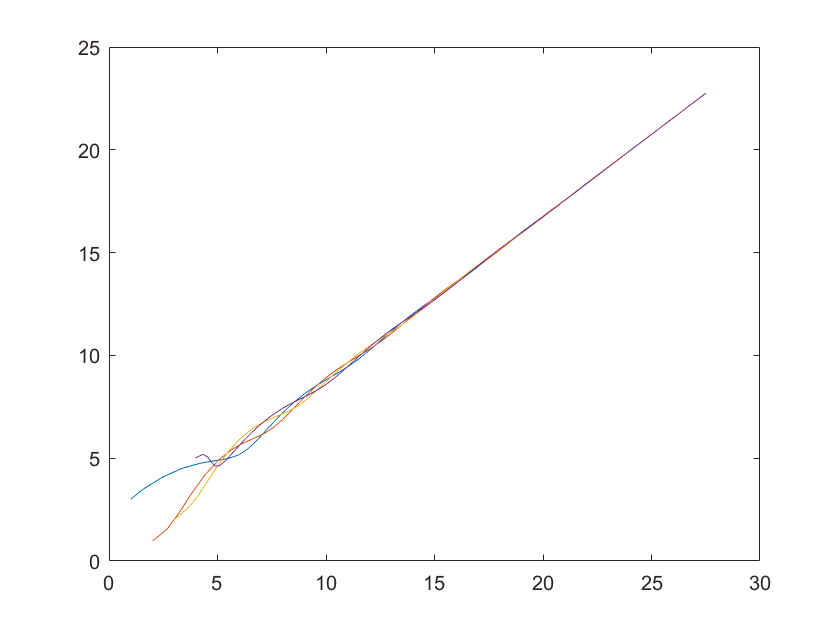

t=x(:,1);
x1=x(:,2);
y1=x(:,3);

x2=x(:,4);
y2=x(:,5);

x3=x(:,6);
y3=x(:,7);

x4=x(:,8);
y4=x(:,9);

plot(x1,y1,x2,y2,x3,y3,x4,y4)

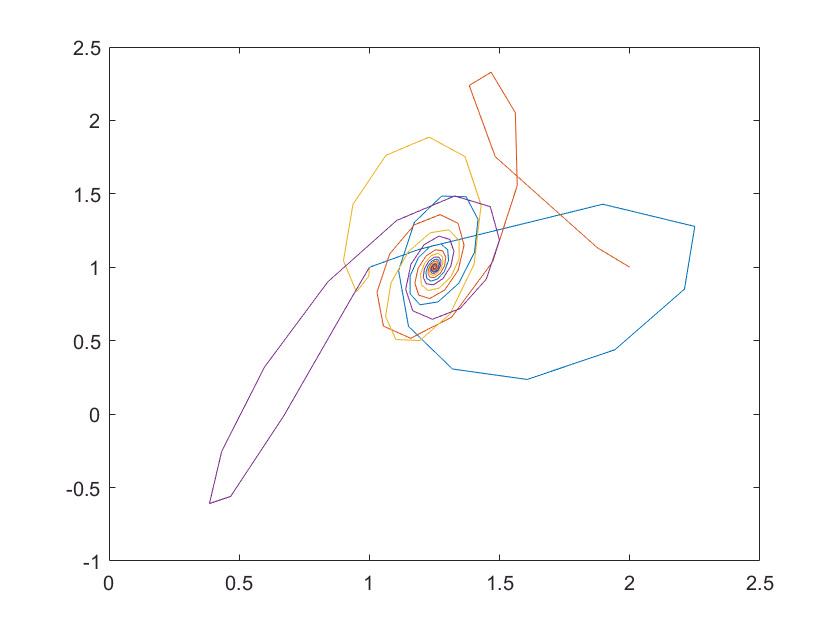


%
vx1=v(:,2);
vy1=v(:,3);

vx2=v(:,4);
vy2=v(:,5);

vx3=v(:,6);
vy3=v(:,7);

vx4=v(:,8);
vy4=v(:,9);

plot(vx1,vy1,vx2,vy2,vx3,vy3,vx4,vy4)

4. target xd,yd

clear;
clc;

%create L1 and initial input x0
L1=[1 0 0 -1;-1 1 0 0;0 -1 1 0;0 0 -1 1];
I2=eye(2);
LK1=kron(L1,I2);
LK1=-LK1;

E=eye(8);

xd=[20 20 30 20 30 10 20 10];
vd=[1 1 1 1 1 1 1 1];

x0=[1 3 2 1 3 2 4 5]';
v0=[2 2 2 2 2 2 2 2]';

display('Initial parameter:')

Initial parameter:


L1,x0,v0

L1 =      1     0     0    -1
    -1     1     0     0
     0    -1     1     0
     0     0    -1     1


x0 =      1
     3
     2
     1
     3
     2
     4
     5


v0 =      2
     2
     2
     2
     2
     2
     2
     2



%simulink and display
sim('cluster_robot_control_4_xd',20);

display('Result display:')

Result display:


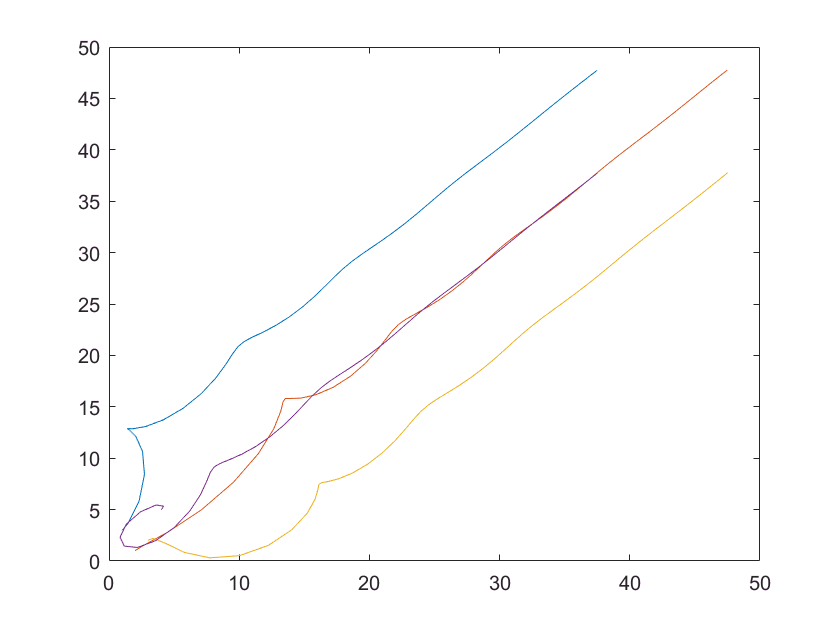

t=x(:,1);
x1=x(:,2);
y1=x(:,3);

x2=x(:,4);
y2=x(:,5);

x3=x(:,6);
y3=x(:,7);

x4=x(:,8);
y4=x(:,9);

plot(x1,y1,x2,y2,x3,y3,x4,y4)

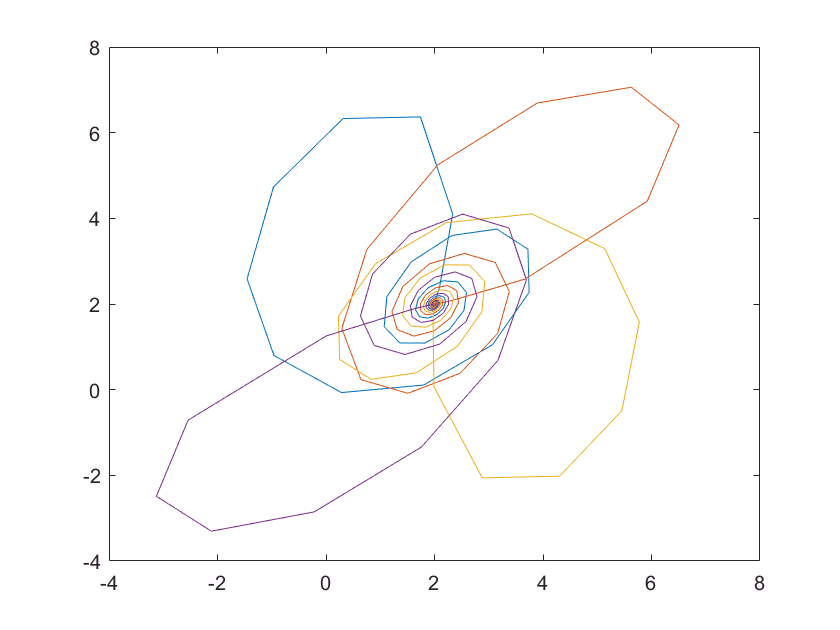


%
vx1=v(:,2);
vy1=v(:,3);

vx2=v(:,4);
vy2=v(:,5);

vx3=v(:,6);
vy3=v(:,7);

vx4=v(:,8);
vy4=v(:,9);

plot(vx1,vy1,vx2,vy2,vx3,vy3,vx4,vy4)

5. feedback loop

clear;
clc;

%create L1 and initial input x0
L1=[1 0 0 -1;-1 1 0 0;0 -1 1 0;0 0 -1 1];
I2=eye(2);
LK1=kron(L1,I2);
LK1=-LK1;

E=eye(8);

xd=[20 20 30 20 30 10 20 10];
vd=[1 1 1 1 1 1 1 1];

x0=[1 3 2 1 3 2 4 5]';
v0=[1 1 2 1 1 1 1 1]';

display('Initial parameter:')

Initial parameter:


L1,x0,v0

L1 =      1     0     0    -1
    -1     1     0     0
     0    -1     1     0
     0     0    -1     1


x0 =      1
     3
     2
     1
     3
     2
     4
     5


v0 =      1
     1
     2
     1
     1
     1
     1
     1



%simulink and display
sim('cluster_robot_control_5_feedback',100);

display('Result display:')

Result display:


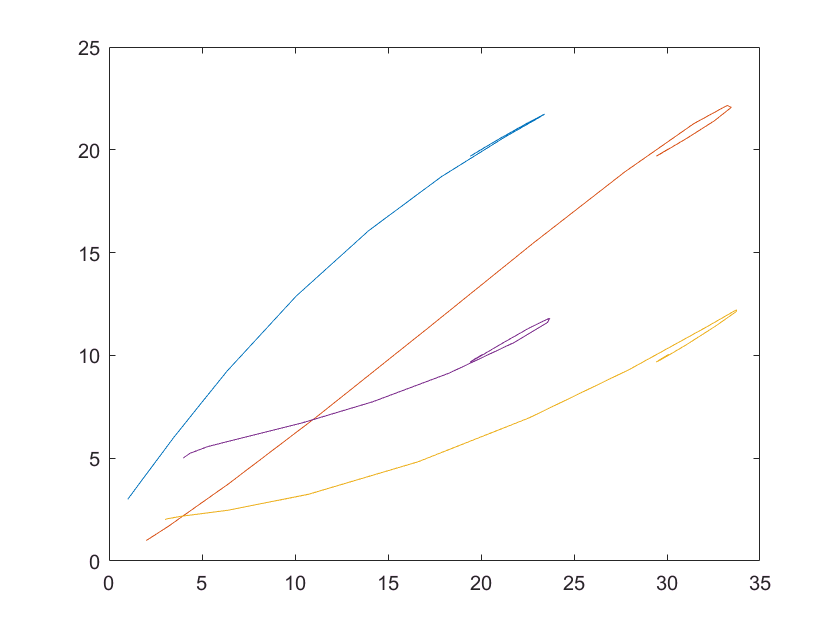

t=x(:,1);
x1=x(:,2);
y1=x(:,3);

x2=x(:,4);
y2=x(:,5);

x3=x(:,6);
y3=x(:,7);

x4=x(:,8);
y4=x(:,9);

plot(x1,y1,x2,y2,x3,y3,x4,y4)

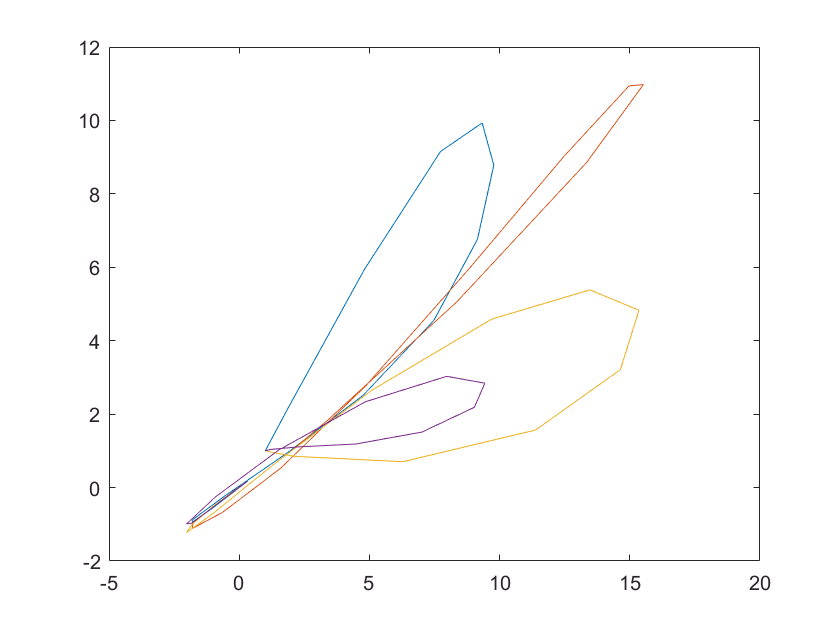


%
vx1=v(:,2);
vy1=v(:,3);

vx2=v(:,4);
vy2=v(:,5);

vx3=v(:,6);
vy3=v(:,7);

vx4=v(:,8);
vy4=v(:,9);

plot(vx1,vy1,vx2,vy2,vx3,vy3,vx4,vy4)

6. moving target

clear;
clc;

%create L1 and initial input x0
L1=[1 0 0 -1;-1 1 0 0;0 -1 1 0;0 0 -1 1];
I2=eye(2);
LK1=kron(L1,I2);
LK1=-LK1;

E=eye(8);

xd=[20 20 30 20 30 10 20 10];
vd=[1 1 1 1 1 1 1 1];

x0=[1 3 2 1 3 2 4 5]';
v0=[1 1 2 1 1 1 1 1]';

display('Initial parameter:')

Initial parameter:


L1,x0,v0

L1 =      1     0     0    -1
    -1     1     0     0
     0    -1     1     0
     0     0    -1     1


x0 =      1
     3
     2
     1
     3
     2
     4
     5


v0 =      1
     1
     2
     1
     1
     1
     1
     1



%simulink and display
sim('cluster_robot_control_6_moving_xd',100);

display('Result display:')

Result display:


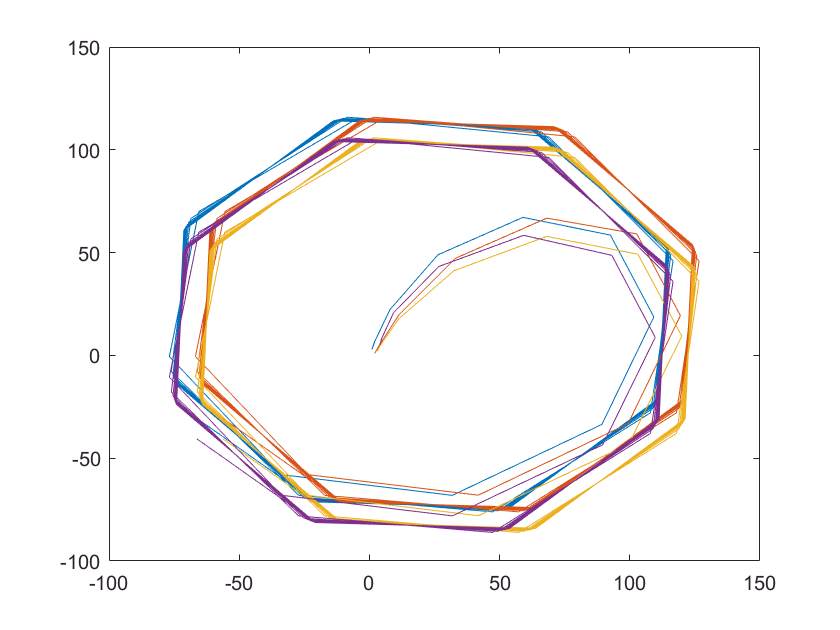

t=x(:,1);
x1=x(:,2);
y1=x(:,3);

x2=x(:,4);
y2=x(:,5);

x3=x(:,6);
y3=x(:,7);

x4=x(:,8);
y4=x(:,9);

plot(x1,y1,x2,y2,x3,y3,x4,y4)

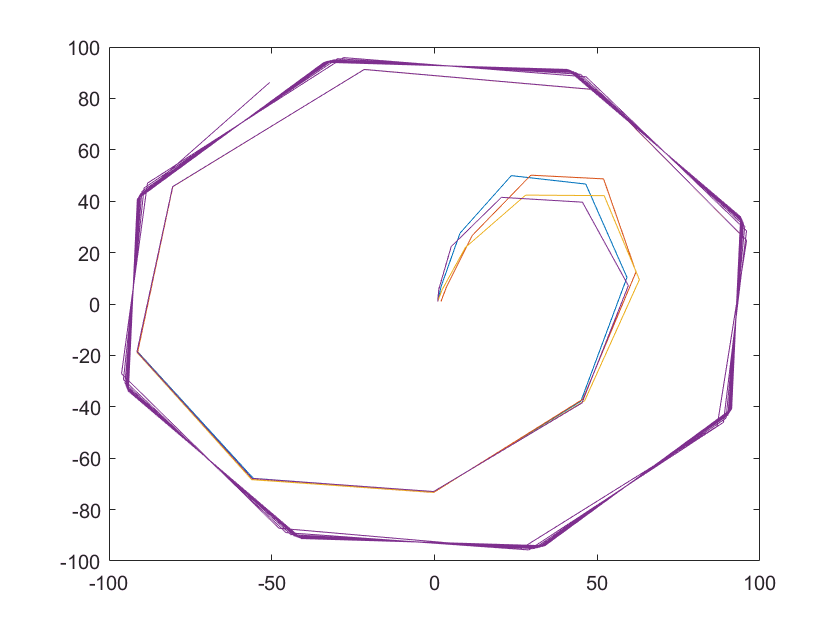


%
vx1=v(:,2);
vy1=v(:,3);

vx2=v(:,4);
vy2=v(:,5);

vx3=v(:,6);
vy3=v(:,7);

vx4=v(:,8);
vy4=v(:,9);

plot(vx1,vy1,vx2,vy2,vx3,vy3,vx4,vy4)

7. rotation

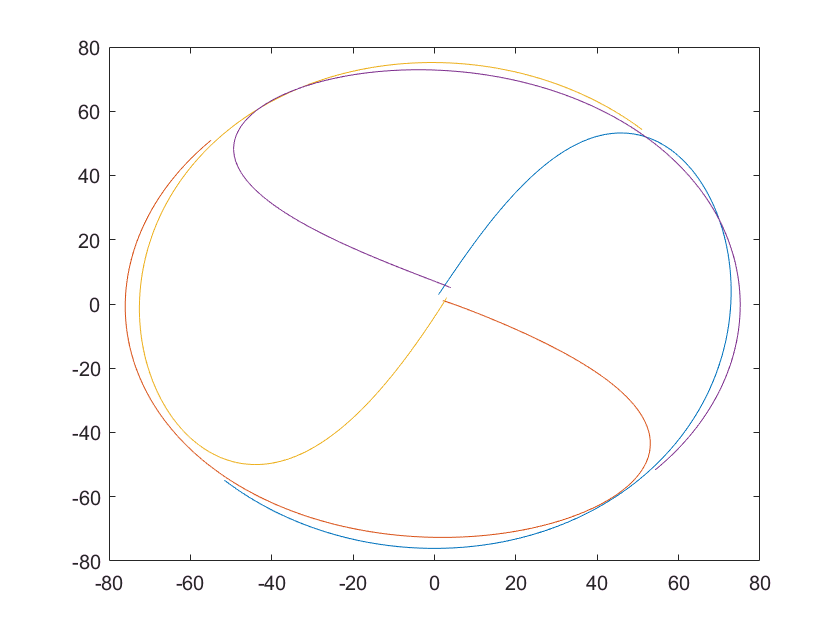

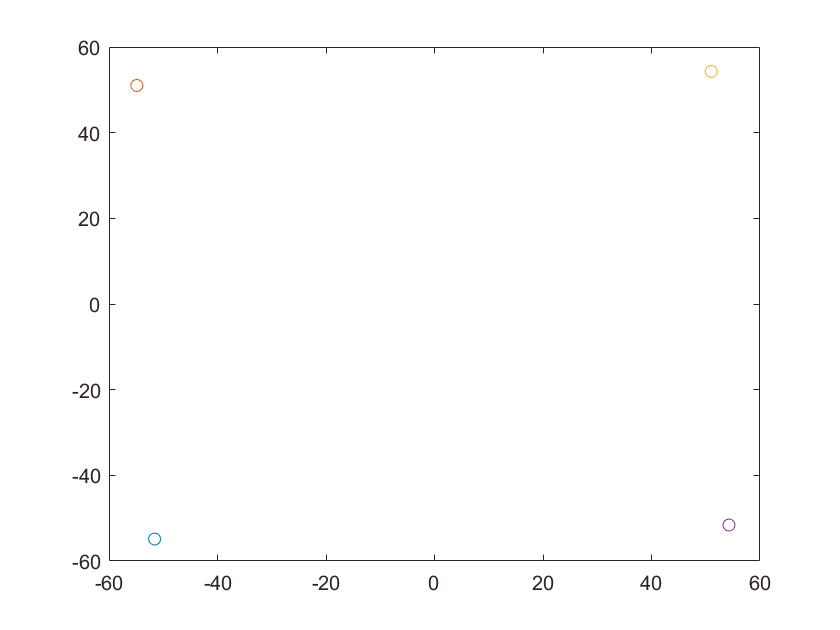

cluster_robot_control_7_rotation

8. final

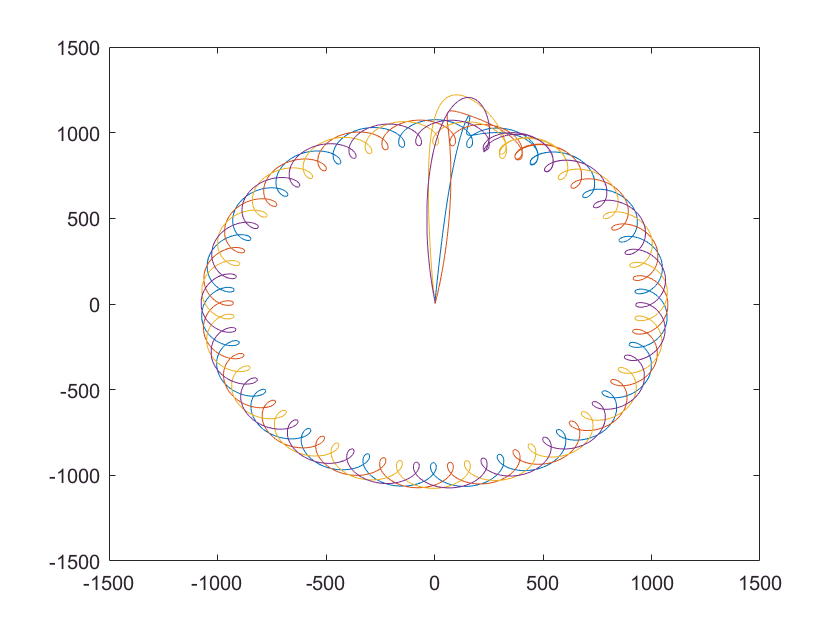

cluster_robot_control_8_final